# Prácticas de Control por Computador (3º GIERM, UMA)

## Práctica 1: Descripción de sistemas discretos en Matlab

#### **Tarea 1**

Escribir la expresión de la función de transferencia discreta (función de transferencia de pulsos) $G\left(z\right)=\frac{z^2 +z+1}{z^3 +3z^2 +5z+1}$ utilizando los comandos **tf** y `zpk` especificando un tiempo de muestreo de $T=0\ldotp 1$ (usar este mismo tiempo de muestreo en el resto de tareas).

% Tu código aquí
T = 0.1;
Gz = tf([1 1 1],[1 3 5 1],T)

Gz =
 
       z^2 + z + 1
  ---------------------
  z^3 + 3 z^2 + 5 z + 1
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


Gz = zpk(Gz)

Gz =
 
            (z^2 + z + 1)
  ---------------------------------
  (z+0.2291) (z^2 + 2.771z + 4.365)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.
Model Properties


#### **Tarea 2**

Hallar la función de transferencia del conjunto en paralelo y expresarla.

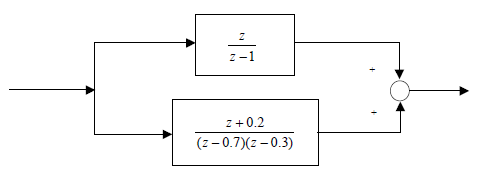

% Tu código aquí
Gz1 = tf([1 0],[1 -1],T)

Gz1 =
 
    z
  -----
  z - 1
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


Gz2 = zpk([-0.2],[0.7 0.3],1,T)

Gz2 =
 
      (z+0.2)
  ---------------
  (z-0.7) (z-0.3)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.
Model Properties


parallel(Gz1,Gz2)

ans =
 
  (z-0.9011) (z^2 + 0.9011z + 0.222)
  ----------------------------------
        (z-1) (z-0.7) (z-0.3)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.
Model Properties


Resultado esperado:

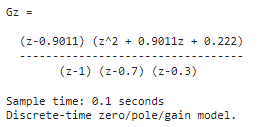

#### **Tarea 3**

Hallar la función de transferencia reducida del conjunto de bloques de la imagen, que posee realimentación negativa:

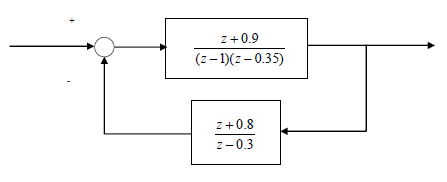

% Tu código aquí
Gz1 = zpk([-0.9],[1 0.35],1,T)

Gz1 =
 
     (z+0.9)
  --------------
  (z-1) (z-0.35)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.
Model Properties


Hz = zpk([-0.8],[0.3],1,T)

Hz =
 
  (z+0.8)
  -------
  (z-0.3)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.
Model Properties


feedback(Gz1,Hz)

ans =
 
           (z+0.9) (z-0.3)
  ----------------------------------
  (z+0.2313) (z^2 - 0.8813z + 2.659)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.
Model Properties


`Resultado esperado:`

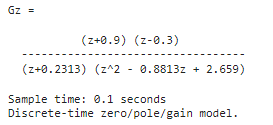

#### **Tarea 4**

Para la función de transferencia $G\left(z\right)=\frac{z^2 +0\ldotp 3z}{z^3 +z^2 +z+0\ldotp 1}$ hallar las raíces de la ecuación característica y obtener la descomposición en fracciones simples a través del comando `residue`.

% Tu código aquí
Gz = tf([1 0.3 0],[1 1 1 0.1],T)

Gz =
 
      z^2 + 0.3 z
  -------------------
  z^3 + z^2 + z + 0.1
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


Gz = zpk(Gz)

Gz =
 
               z (z+0.3)
  -----------------------------------
  (z+0.1109) (z^2 + 0.8891z + 0.9014)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.
Model Properties


[num,den]= tfdata(Gz)

num = 1×1 cell array
    {[0 1 0.3000 0]}


den = 1×1 cell array
    {[1 1.0000 1.0000 0.1000]}


raices = roots([1 1 1 0.1])

raices =   -0.4445 + 0.8389i
  -0.4445 - 0.8389i
  -0.1109 + 0.0000i


[r,p,k] = residue([1 0.3 0],[1 1 1 0.1])

r =    0.5129 + 0.1471i
   0.5129 - 0.1471i
  -0.0257 + 0.0000i


p =   -0.4445 + 0.8389i
  -0.4445 - 0.8389i
  -0.1109 + 0.0000i



k =

     []



`Resultado esperado:`

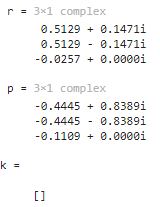

#### **Tarea 5**

Hallar la respuesta temporal ante escalón unitario del sistema con un cero en $z_{{\;}_0 } =-0\ldotp 9$, dos polos situados en $z_{\textrm{p1}} =1$ y $z_{\textrm{p2}} =0\ldotp 8$ y ganancia $0\ldotp 05$ en bucle cerrado y realimentación unitaria. 

% Tu código aquí
Gz = zpk([-0.9],[1 0.8],1,T)

Gz =
 
     (z+0.9)
  -------------
  (z-1) (z-0.8)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.
Model Properties


Gbz = feedback(0.05*Gz,1)

Gbz =
 
      0.05 (z+0.9)
  ---------------------
  (z^2 - 1.75z + 0.845)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.
Model Properties


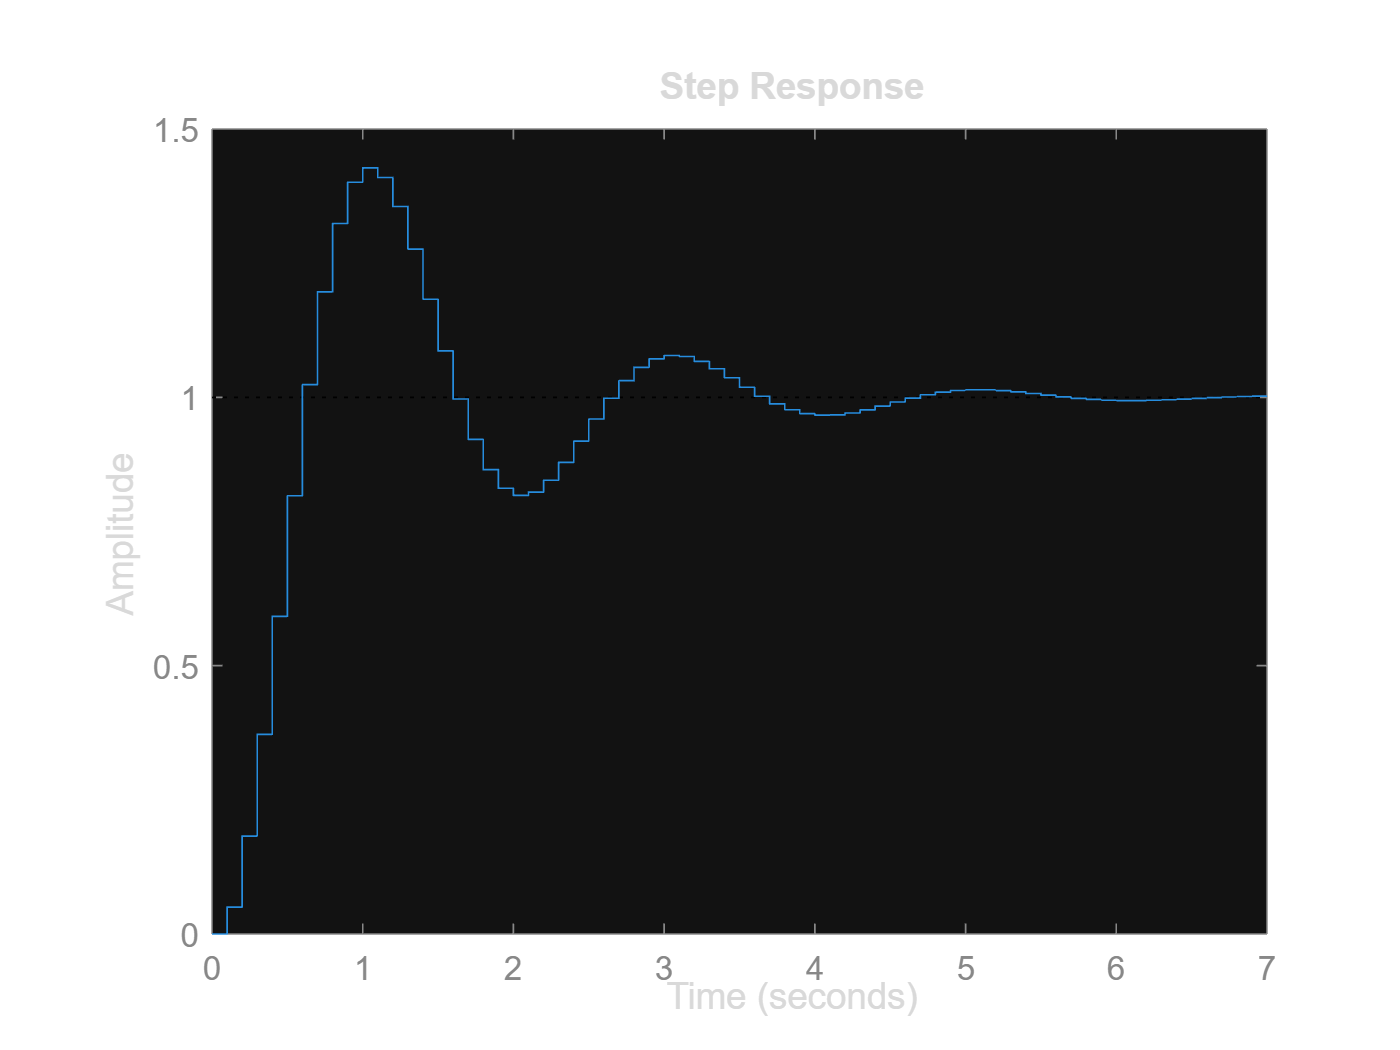

step(Gbz,7)

`Resultado esperado:`

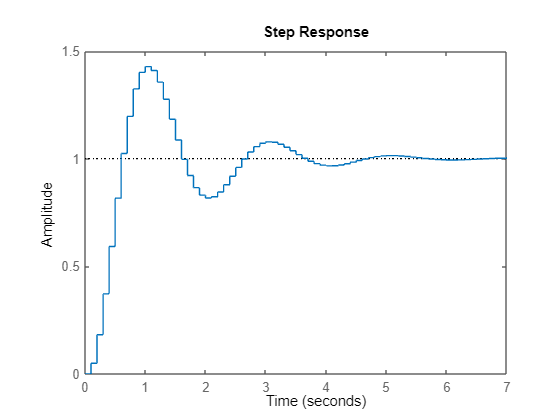

Dibujar el lugar de las raíces usando además el comando `zgrid`.

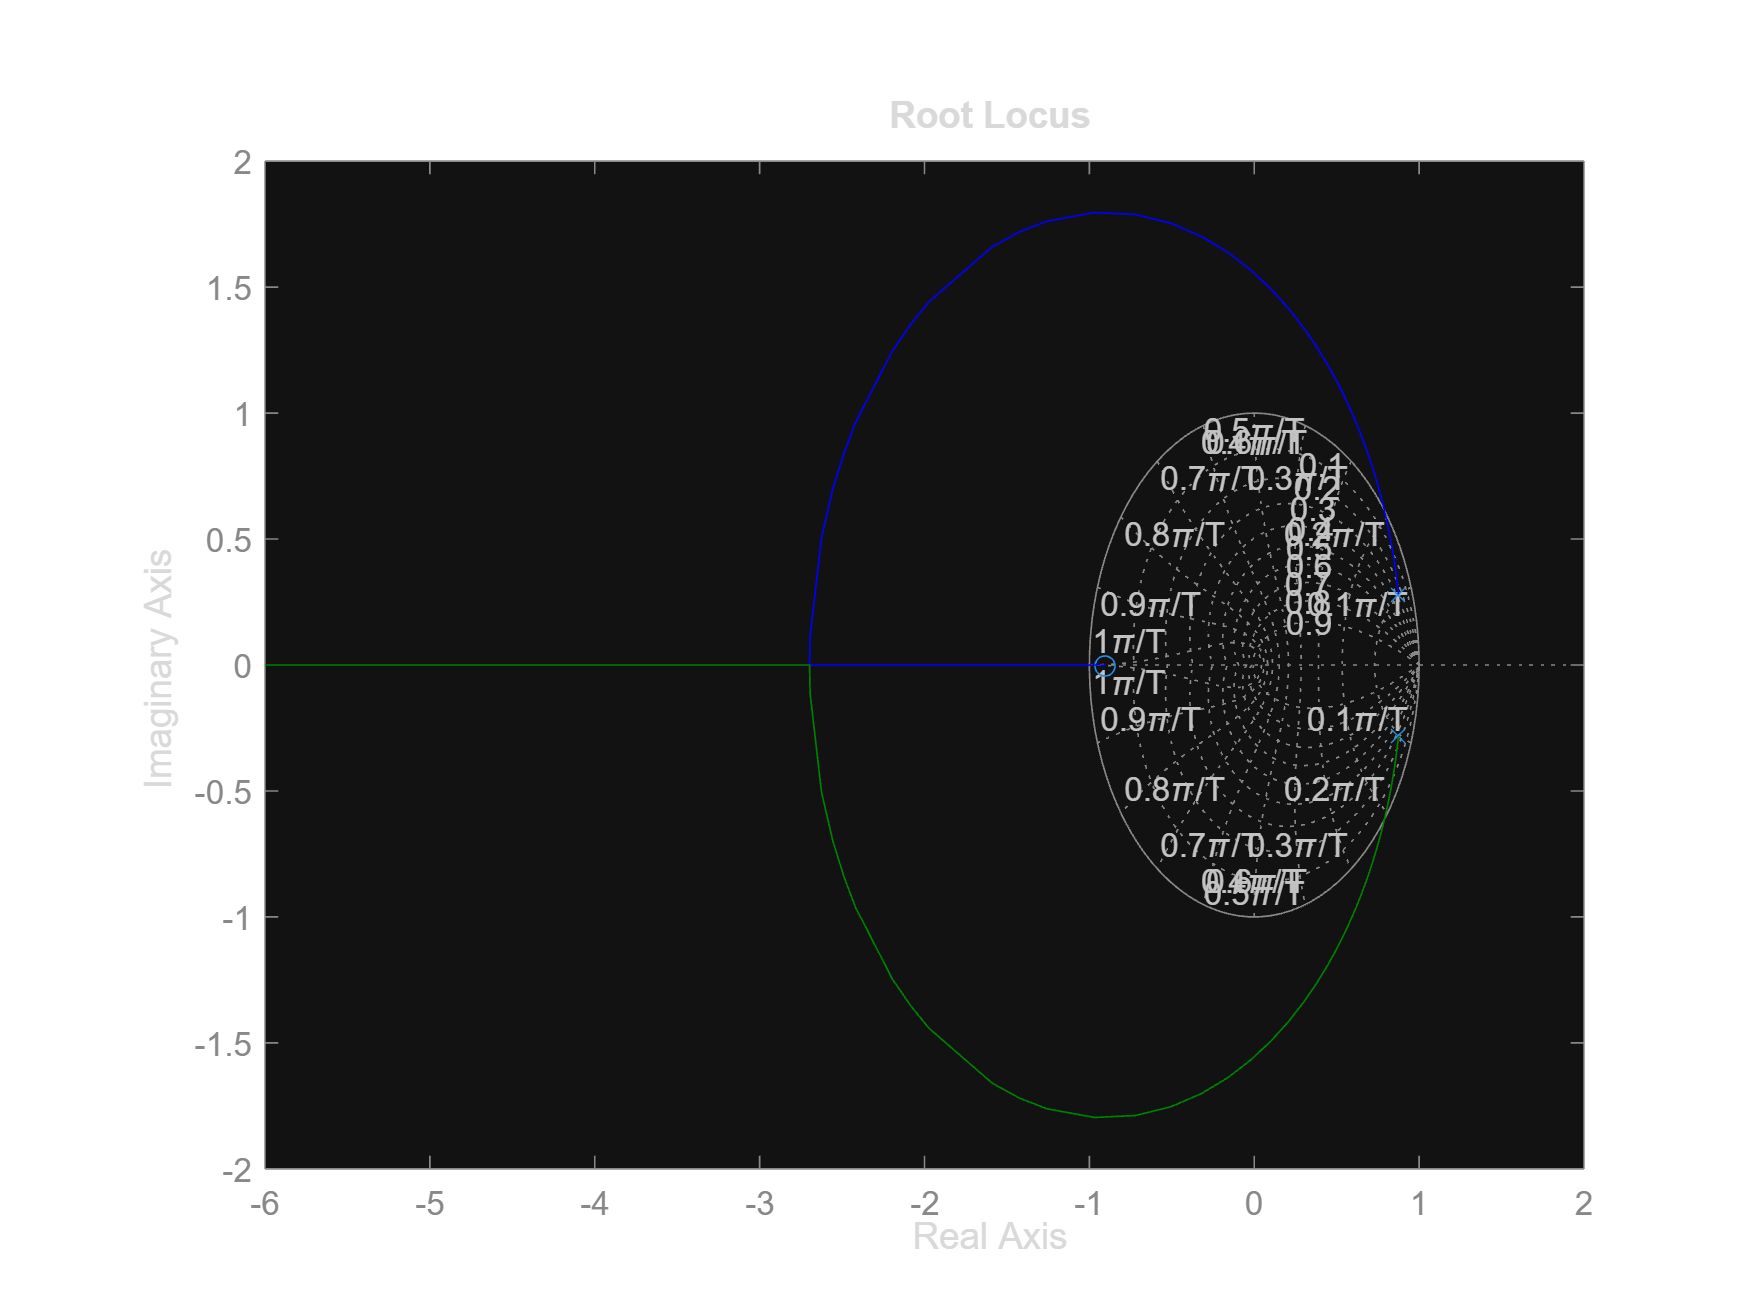

% Tu código aquí
rlocus(Gbz)
zgrid

`Resultado esperado:`

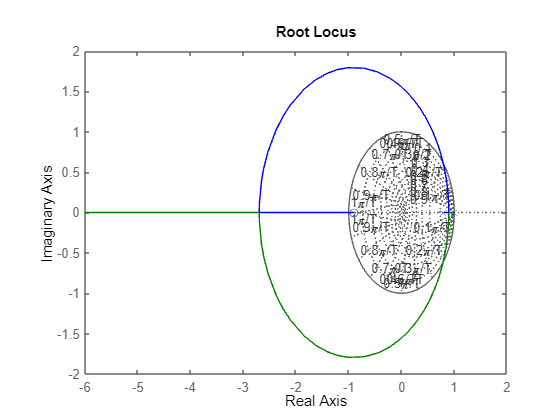

#### **Tarea 6**

Simular las respuesta del sistema $G\left(z\right)=\frac{z}{z^2 -1\ldotp 7z+0\ldotp 7}$ en bucle cerrado y con realimentación unitaria ante entradas impulso, escalón y rampa durante 3 segundos, graficándolas en la misma figura con `subplot`. Utilizando el comando de representación de señales discretas `stem `para mostrar las respuestas del sistema.

% Tu código aquí
Gz = tf([1 0],[1 -1.7 0.7],T)

Gz =
 
          z
  -----------------
  z^2 - 1.7 z + 0.7
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


Gbz = feedback(Gz,1)

Gbz =
 
          z
  -----------------
  z^2 - 0.7 z + 0.7
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


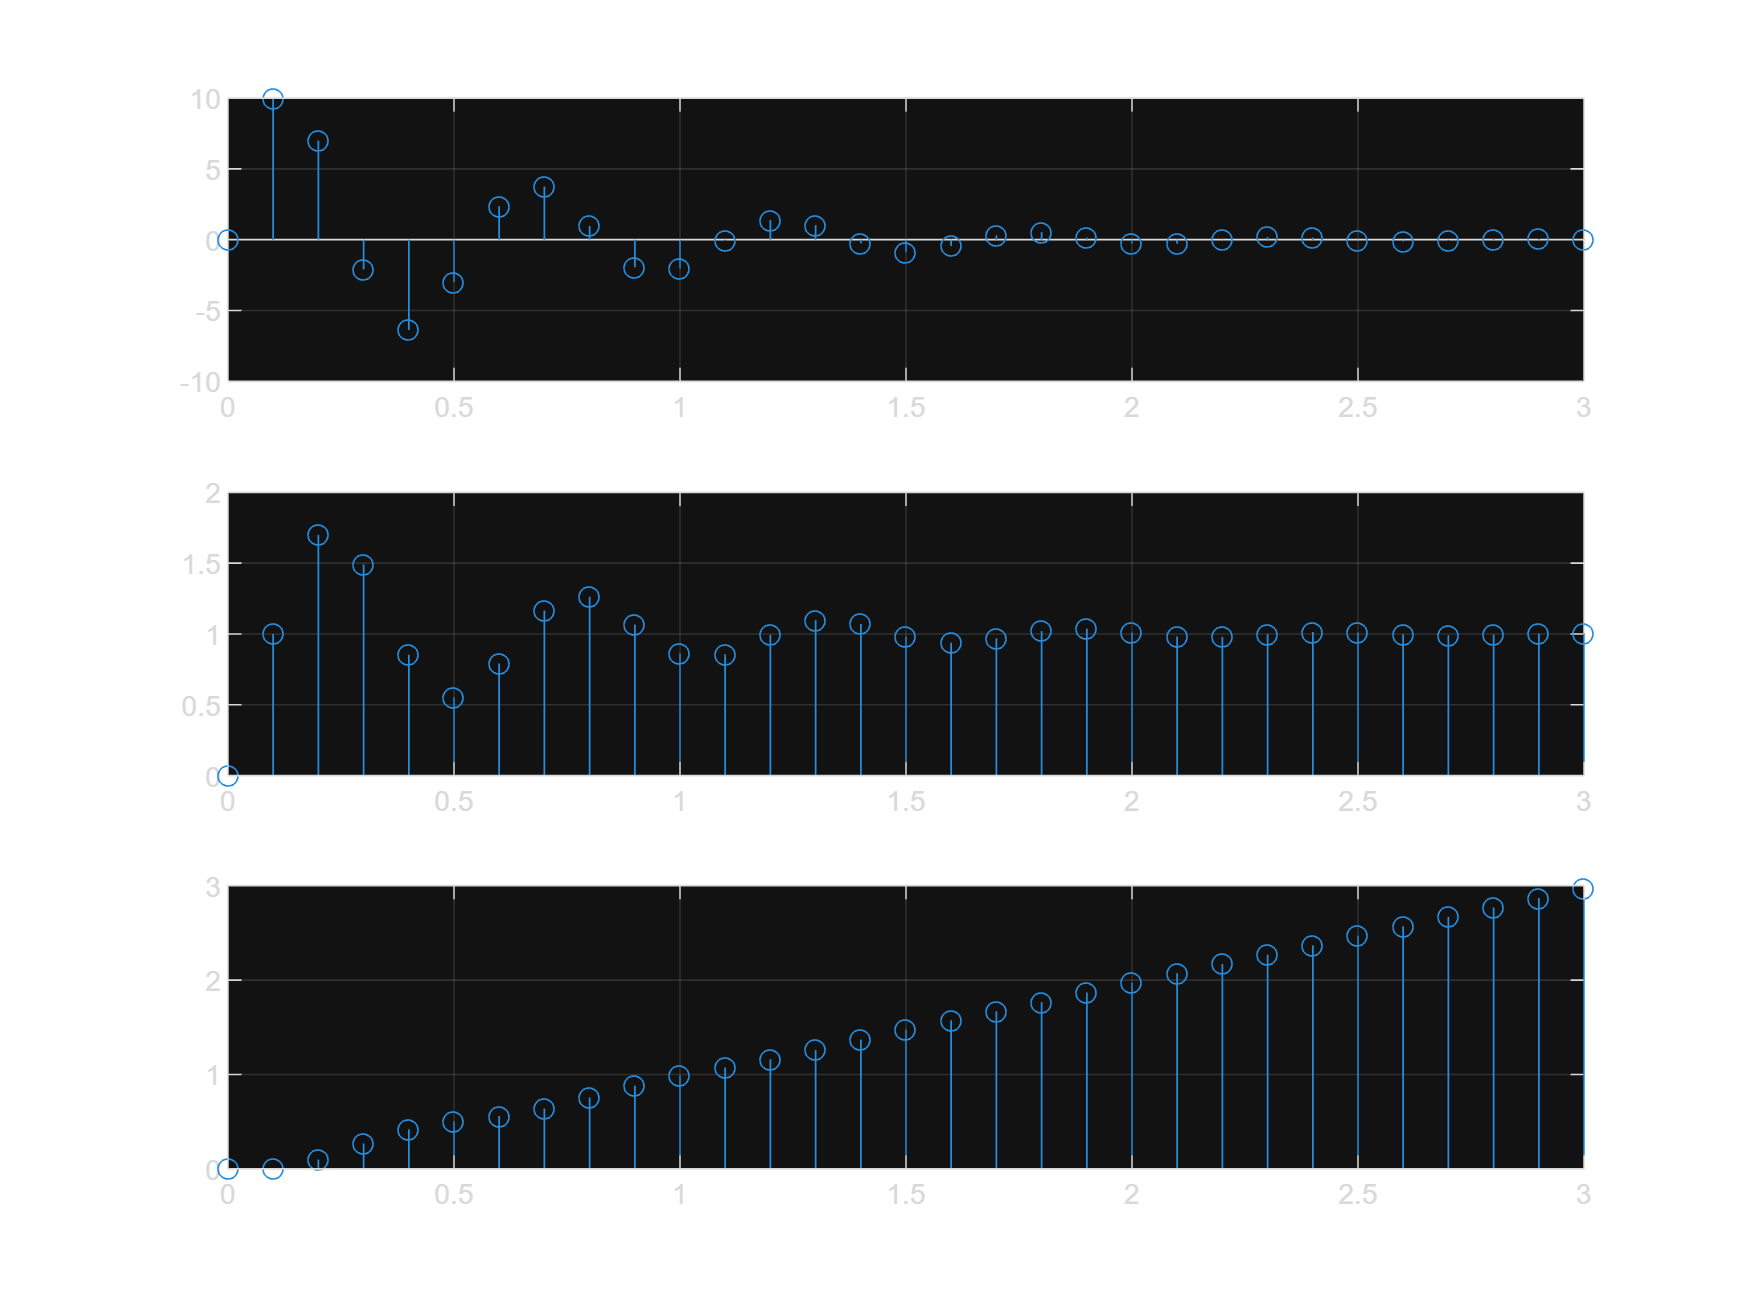

grid
subplot(3,1,1)
t = 0:T:3;
stem(t,impulse(Gbz,t));
grid 
subplot(3,1,2)
stem(t,step(Gbz,t))
grid
subplot(3,1,3)
stem(t,lsim(Gbz,t))
grid

`Resultado esperado:`